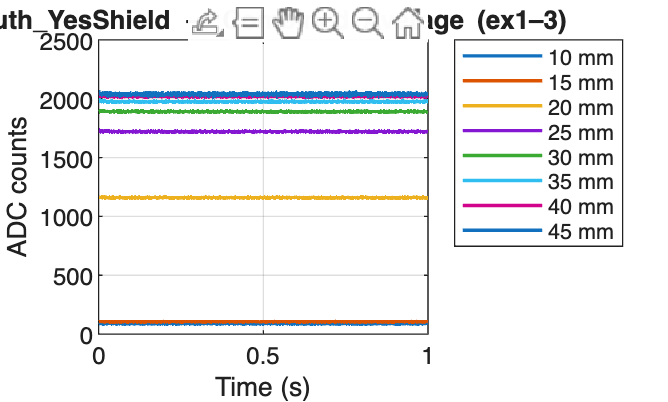

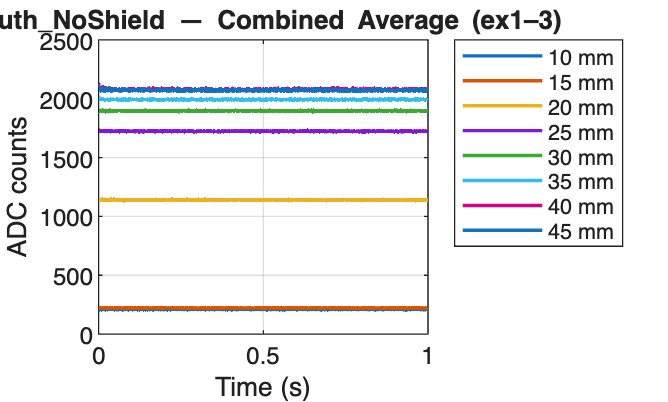

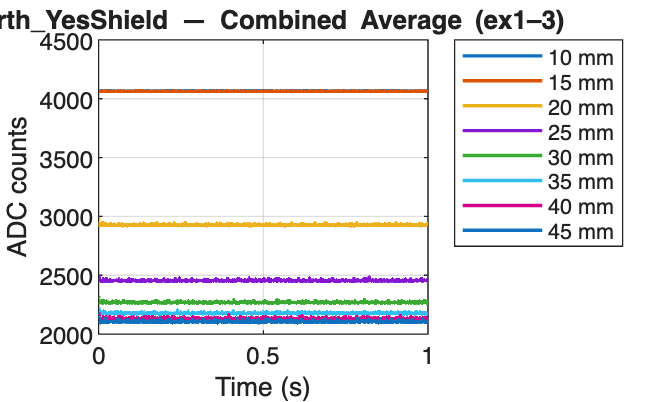

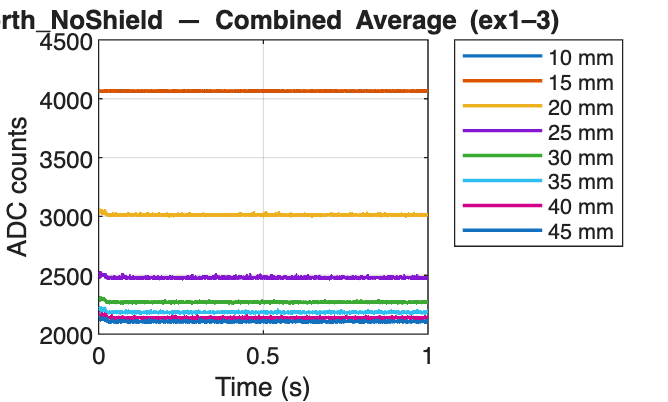

%% === Combine all ex (ex1–ex3) into averaged curves per distance (FIXED) ===
clc; clear; close all;

ROOT  = '/Users/thadzy/Documents/Thadzy/RMX-Magnetic/Magnetic';
cases = {'South_YesShield','South_NoShield','North_YesShield','North_NoShield'};

for ci = 1:numel(cases)
    caseDir = fullfile(ROOT, cases{ci});
    if ~isfolder(caseDir)
        warning('Skip missing: %s', caseDir); continue;
    end

    exFolders = dir(fullfile(caseDir, 'ex*'));
    exFolders = exFolders([exFolders.isdir]);
    if isempty(exFolders)
        warning('No ex folders in %s', caseDir); continue;
    end

    % >>> สร้าง distList จากชื่อไฟล์ใน ex แรก และ "กรองเฉพาะชื่อที่เป็นตัวเลข"
    mats = dir(fullfile(exFolders(1).folder, exFolders(1).name, '*.mat'));
    dnums = arrayfun(@(d) extractDistance(d.name), mats);
    distList = unique(sort(dnums(~isnan(dnums))));   % กรอง NaN ออก
    if isempty(distList)
        warning('No numeric distance files found in %s', fullfile(exFolders(1).folder, exFolders(1).name));
        continue;
    end

    avgDir = fullfile(caseDir, 'avg_combined');
    if ~exist(avgDir, 'dir'), mkdir(avgDir); end

    allDist = [];
    allMeanADC = [];
    legends = {};

    figure('Name', cases{ci}, 'Color', 'w'); hold on; grid on; box on;

    for di = 1:numel(distList)
        d = distList(di);

        Y = []; t_ref = [];
        for ei = 1:numel(exFolders)
            fpath = fullfile(caseDir, exFolders(ei).name, sprintf('%d.mat', d));
            if ~isfile(fpath), continue; end
            try
                [t, y] = loadTimeseriesRobust(fpath);
                % บังคับชนิดข้อมูล
                if isdatetime(t) || isduration(t)
                    t = seconds(t - t(1));   % เริ่มที่ 0 s
                else
                    t = double(t(:));
                end
                y = double(y(:));
                Y = [Y, y];           %#ok<AGROW>
                if isempty(t_ref), t_ref = t; end
            catch ME
                warning('Skip %s (%s)', fpath, ME.message);
            end
        end

        if isempty(Y)
            warning('No data for distance %d mm in %s', d, caseDir);
            continue;
        end

        y_mean = mean(Y, 2, 'omitnan');
        allDist(end+1)    = d;                                 %#ok<SAGROW>
        allMeanADC(end+1) = mean(y_mean, 'omitnan');           %#ok<SAGROW>

        % Save averaged CSV ต่อระยะ
        T = table(t_ref, y_mean, 'VariableNames', {'t_s','ADC_mean'});
        writetable(T, fullfile(avgDir, sprintf('%d.csv', d)));

        % Plot
        plot(t_ref, y_mean, 'LineWidth', 1.3);
        legends{end+1} = sprintf('%d mm', d);
    end

    if isempty(legends)
        warning('No curves plotted for %s', cases{ci});
        close(gcf);  % ปิดรูปว่าง
        continue;
    end

    xlabel('Time (s)');
    ylabel('ADC counts');
    title(sprintf('%s — Combined Average (ex1–3)', strrep(cases{ci},'_','\_')));
    legend(legends, 'Location','bestoutside');
    xlim tight; ylim auto;

    exportgraphics(gcf, fullfile(caseDir, sprintf('%s_combined_avg.png', cases{ci})), 'Resolution', 150);

    % สรุป mean ต่อระยะ
    summary = table(allDist(:), allMeanADC(:), 'VariableNames', {'Distance_mm','Mean_ADC'});
    writetable(summary, fullfile(avgDir, 'summary_avg.csv'));
end


disp('✅ Combined averaging across ex1–ex3 completed.');

✅ Combined averaging across ex1–ex3 completed.



%% ===== Helpers =====
function d = extractDistance(fname)
    % ดึงตัวเลขจากชื่อไฟล์ เช่น '15.mat' → 15; อื่น ๆ → NaN
    tok = regexp(fname, '^(\d+)\.mat$', 'tokens', 'once'); % เข้มขึ้น: ต้องเป็นตัวเลขล้วนตามด้วย .mat
    if isempty(tok), d = NaN; else, d = str2double(tok{1}); end
end

function [t, y] = loadTimeseriesRobust(fpath)
    S = load(fpath);
    fn = fieldnames(S);
    ts = [];

    % timeseries ตรง ๆ
    for i = 1:numel(fn)
        v = S.(fn{i}); if isa(v,'timeseries'), ts = v; break; end
    end
    % struct.data
    if isempty(ts)
        for i = 1:numel(fn)
            v = S.(fn{i});
            if isstruct(v) && isfield(v,'data') && isa(v.data,'timeseries')
                ts = v.data; break;
            end
        end
    end
    % Dataset
    if isempty(ts)
        for i = 1:numel(fn)
            v = S.(fn{i});
            if isa(v,'Simulink.SimulationData.Dataset')
                for k = 1:v.numElements
                    el = v{k};
                    if isprop(el,'Values') && isa(el.Values,'timeseries')
                        ts = el.Values; break;
                    end
                end
                if ~isempty(ts), break; end
            end
        end
    end
    if isempty(ts), error('No timeseries found in %s', fpath); end

    t = ts.Time(:);
    y = squeeze(ts.Data);
end
